% ---------- load ----------
T = readtable('C:\Users\washa\OneDrive\Desktop\APRL\Vehicle\Calculators and Research\Hot Fire Thrust Curve\20251101-mu2cyf2-1_v2-thrust.csv');    % adjust filename
% assume csv has columns named 'time' (s) and 'thrust' (N). If not, adjust.
t = T.time;
F_raw = T.thrust;

% ---------- sample frequency ----------
dt = mean(diff(t));            % computed from your timestamps
fs = 1/dt;
fprintf('Estimated fs = %.3f Hz\n', fs);

Estimated fs = 258.355 Hz


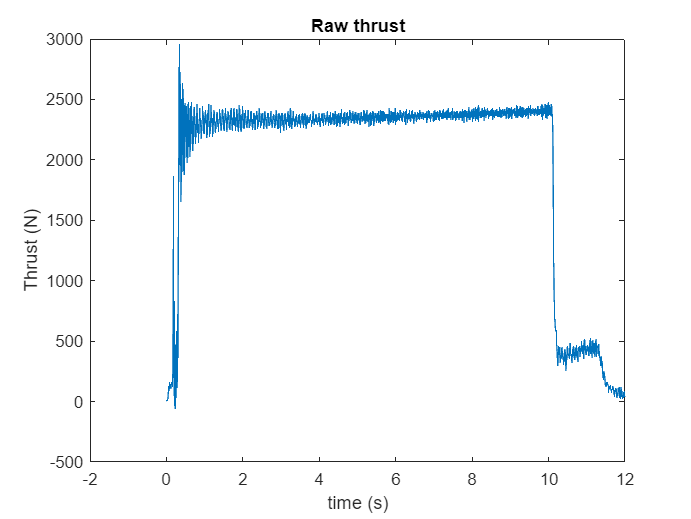


% ---------- quick plot of raw ----------
figure; plot(t, F_raw);
xlabel('time (s)'); ylabel('Thrust (N)');
title('Raw thrust');

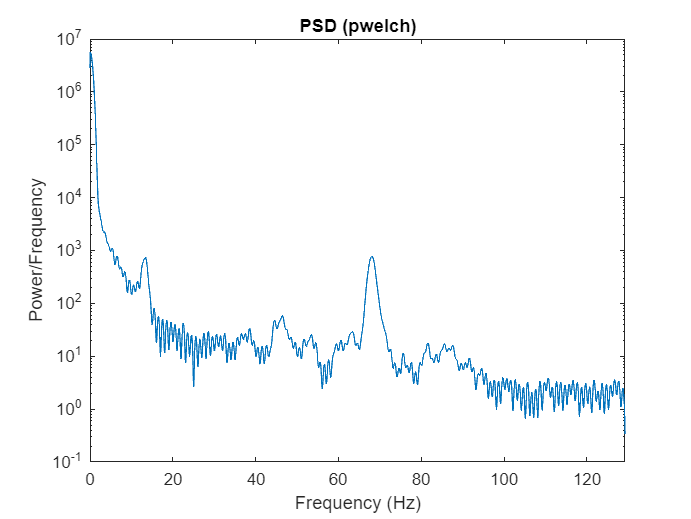


% ---------- baseline removal (optional but recommended) ----------
% use early segment before ignition as baseline; adjust window length if needed
pre_end_idx = find(t >= t(1) + 0.2, 1); % first 0.2 s as baseline (adjustable)
if isempty(pre_end_idx), pre_end_idx = round(0.1*fs); end
baseline = mean(F_raw(1:pre_end_idx));
F0 = F_raw - baseline;

% ---------- PSD to choose cutoff ----------
% this helps see where the signal energy lives
nfft = 2^nextpow2(length(F0));
[pxx,f] = pwelch(F0, round(fs), [], nfft, fs);
figure; semilogy(f, pxx);
xlabel('Frequency (Hz)'); ylabel('Power/Frequency');
xlim([0, fs/2]); title('PSD (pwelch)');

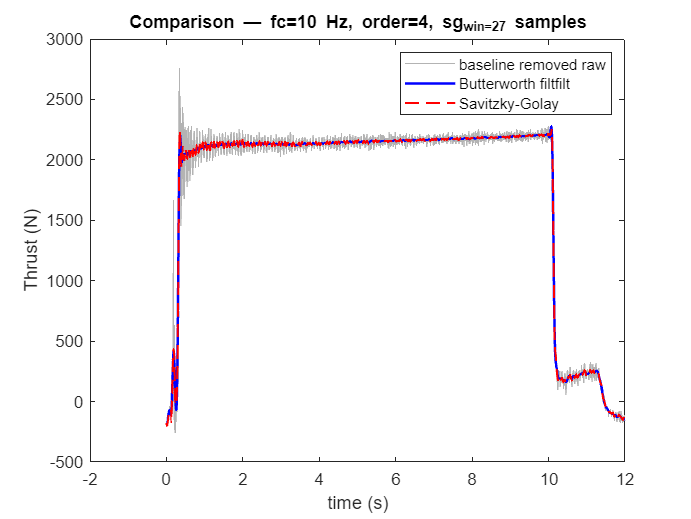


% ---------- heuristic cutoff choices ----------
% Typical rocket static thrust changes are low-frequency. Try 10-30 Hz.
% Start with fc = 20 Hz (adjust after checking PSD).
fc = 10;              % Hz - change to 10, 30, etc to compare
order = 4;            % Butterworth order

% ---------- butterworth design & zero-phase filtering ----------
Wn = fc/(fs/2);       % normalized cutoff (0..1)
[b,a] = butter(order, Wn, 'low');
F_butter = filtfilt(b, a, F0);   % zero phase

% ---------- Savitzky-Golay alternative ----------
% choose window length as a fraction of fs. window must be odd.
win_seconds = 0.1; % 50 ms smoothing window (tune); smaller preserves faster transients
winlen = round(win_seconds * fs);
if mod(winlen,2)==0, winlen = winlen+1; end
polyorder = 3;       % cubic poly; polyorder < winlen
F_sg = sgolayfilt(F0, polyorder, winlen);

% ---------- plot comparison ----------
figure;
plot(t, F0, 'Color',[0.7 0.7 0.7]); hold on;
plot(t, F_butter, 'b', 'LineWidth', 1.5);
plot(t, F_sg, 'r--', 'LineWidth', 1.2);
xlabel('time (s)'); ylabel('Thrust (N)');
legend('baseline removed raw','Butterworth filtfilt','Savitzky-Golay');
title(sprintf('Comparison — fc=%g Hz, order=%d, sg_win=%d samples', fc, order, winlen));


% ---------- filtered data if desired ----------
T_out = table(t, F_butter, ...
    'VariableNames', {'time','thrust_filtered'});
writetable(T_out, 'thrust_filtered_only.csv');